# **Official Landing Gear Code**

Juan Pablo Meda Castro s3296369

clc;clear;close

## *INPUT SECTION*

### **Code input variables**

Airplane_mass = 97; % Airplane's mass [kg]
SF = 2.0; % Safety factor
g = 9.81; % Gravitational acceleration [m/s^2]

### Material data

Strut material: Aluminum 2024-T6

E_strut = 72.4e9; % Elastic modulus [Pa]
Ys_strut = 372e6; % Yield strength [Pa]
Rho_strut = 2780; % Density [kg/m^3]

### Struts data

Landing gear configuration: Taildragger, two wheels at the front, one at the back.

K = 2; % Effective length factor (one fixed end and one free end)

BW_D = 0.05; % Back wheel diameter [m]
FW_D = 0.175; % Front wheel diameter [m]

### Fuselage length

Fuselage_L = 3; % Fuselage length;

D_bwt_wheels = 2; % Distance between wheels [m]

Distance_from_ground = 0.05; % Length of the back wheel strut

alpha = 13; % Fuselage angle with respect to the ground [deg]

### Impact data

% Impact velocity
Impact_v = 4; % For a hard landing v = 4 [m/s]

% Impact distance
Impact_d = 0.1; % Distance from the ground [m]

### Drag data

Rho_sealevel = 1.225; % Air's density at sea level [kg/m^3]
viscosity_sealevel = 1.789e-5; % Air's viscosity at sea level [kg/ms]
Airplane_velocity = 42; % Airplane cruise speed [m/s]

## *CALCULATIONS*

Back_strut_L = BW_D / 2; % Back strut length [m]
Frontal_strut_L = (D_bwt_wheels * tan(alpha) + Distance_from_ground) - (FW_D/2); % Frontal strut length [m]

### Airplane's weight

Weight = Airplane_mass * g; % Airplane's weight [N]

### Impact load

KE = 0.5 * Airplane_mass * Impact_v^2; % Kinetic energy [Nm]
F = KE / Impact_d; % Force due to kinetic energy [N]

Impact_P = Weight + F; % Impact load due to hard landing [N]

### Critical load

Pcr = Impact_P * SF; % Critical load [N]

### Effective length for each strut 

Le_Front_Strut = K * Frontal_strut_L; % [m]
Le_Back_Strut = K * Back_strut_L; % [m]

### Strut radius to prevent buckling from critical load

Front_Strut_Radius_buckling = sqrt(sqrt(((Pcr/2) * Le_Front_Strut^2) / (pi^3 * E_strut * 0.25))); % Frontal strut radius [m]
Back_Strut_Radius_buckling =  sqrt(sqrt(((Pcr) * Le_Back_Strut^2) / (pi^3 * E_strut * 0.25))); % Back strut radius [m]

Front_Strut_D = 2 * Front_Strut_Radius_buckling; % Front Strut diameter [m]
Back_Strut_D = 2 * Back_Strut_Radius_buckling; % Back Strut diameter [m]


r2 = 0.03;
r1 = sqrt((r2^2)-((Pcr*Le_Front_Strut^2*4)/(pi^3 * E_strut)));
A = pi * (r2^2 - r1^2);
t = r2 - r1;

V = A * Frontal_strut_L;
mass = V * Rho_strut;

### Strut area to prevent buckling from critical load

Front_Strut_A = pi * Front_Strut_Radius_buckling^2; % [m^2]
Back_Strut_A = pi * Back_Strut_Radius_buckling^2; % [m^2]

### Strut stress calculation

% Critical buckling stress
Front_Strut_cr_Stress = (Pcr/2) / Front_Strut_A; % [Pa]
Back_Strut_cr_Stress = (Pcr) / Back_Strut_A; % [Pa]

% Compressive stress due to weight
Front_Strut_Compressive = Weight / Front_Strut_A; % [Pa]
Back_Strut_Compressive = Weight / Back_Strut_A; % [Pa]

% Impact stress due to impact force
Front_Strut_Impact_Stress = Impact_P / Front_Strut_A; % [Pa]
Back_Strut_Impact_Stress = Impact_P / Back_Strut_A; % [Pa]

### Strut mass

Frontal_strut_V = Front_Strut_A * Frontal_strut_L; % Frontal strut volume [m^3]
Back_strut_V = Back_Strut_A * Back_strut_L; % Back strut volume [m^3]

Frontal_Strut_mass = Frontal_strut_V * Rho_strut; % Frontal strut mass [kg]
Back_Strut_mass = Back_strut_V * Rho_strut; % Back strut mass [kg]

Total_LG_mass = (2*Frontal_Strut_mass) + (Back_Strut_mass); % Total landing gear mass [kg]

### Landing gear drag

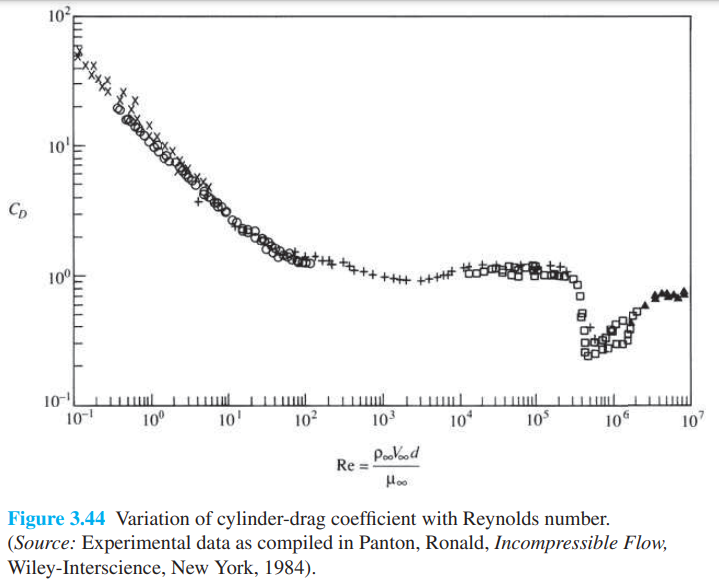

% Reynold's number
Re_Frontal_strut = (Rho_sealevel * Airplane_velocity * Front_Strut_D) / viscosity_sealevel; % Reynold's number frontal strut
Re_Back_strut = (Rho_sealevel * Airplane_velocity * Back_Strut_D) / viscosity_sealevel; % Reynold's number back strut

% Drag coefficient
cD_Frontal_strut = 1; % Drag coefficient from figure 3.44 of Anderson's Fundamental of Aerodynamics, 6th edition
cD_Back_strut = 0.98; % Drag coefficient from figure 3.44 of Anderson's Fundamental of Aerodynamics, 6th edition

% Wetted area
WA_FS = (pi * Front_Strut_D) * Frontal_strut_L; % Wetted area frontal strut [m^2]
WA_BS = (pi * Back_Strut_D) * Back_strut_L; % Wetted area back strut [m^2]

% Drag force
DragF_FS = (0.5 * Rho_sealevel * Airplane_velocity^2 * WA_FS * cD_Frontal_strut); % Drag force frontal strut [N]
DragF_BS = (0.5 * Rho_sealevel * Airplane_velocity^2 * WA_BS * cD_Back_strut); % Drag force back strut [N]

% Total drag force
Total_DragF_LG = (2*DragF_FS) + (DragF_BS); % Landing gear drag force [N]

## *RESULTS*

### Material strength

variables_1 = {'Material Yield Strength', (Ys_strut/(1e6)), 'MPa';
               'Impact stress on front strut', (Front_Strut_Impact_Stress/(1e6)), 'MPa';
               'Impact stress on back strut', (Back_Strut_Impact_Stress/(1e6)), 'MPa';
               'Critical buckling stress on front strut', (Front_Strut_cr_Stress/(1e6)), 'MPa';
               'Critical buckling stress on back strut', (Back_Strut_cr_Stress/(1e6)), 'MPa'};
disp(variables_1)

    {'Material Yield Strength'                }    {[     372]}    {'MPa'}
    {'Impact stress on front strut'           }    {[ 12.5243]}    {'MPa'}
    {'Impact stress on back strut'            }    {[314.7585]}    {'MPa'}
    {'Critical buckling stress on front strut'}    {[ 12.5243]}    {'MPa'}
    {'Critical buckling stress on back strut' }    {[629.5170]}    {'MPa'}



### Strut diameters

variables_2 = {'Frontal strut diameter', (Front_Strut_D * 100), 'cm';
               'Back strut diameter', (Back_Strut_D * 100), 'cm'};
disp(variables_2)

    {'Frontal strut diameter'}    {[2.9760]}    {'cm'}
    {'Back strut diameter'   }    {[0.5936]}    {'cm'}



### Landing gear mass

variables_3 = {'Frontal strut mass', (Frontal_Strut_mass), 'kg';
               'Back strut individual mass', (Back_Strut_mass), 'kg';
               'Total landing gear mass', (Total_LG_mass), 'kg'};
disp(variables_3)

    {'Frontal strut mass'        }    {[1.7182]}    {'kg'}
    {'Back strut individual mass'}    {[0.0019]}    {'kg'}
    {'Total landing gear mass'   }    {[3.4383]}    {'kg'}



### Landing gear drag force

variables_4 = {'Frontal strut drag force', (DragF_FS), 'N';
               'Back strut individual drag force', (DragF_BS), 'N';
               'Total landing gear drag force', (Total_DragF_LG), 'N'};
disp(variables_4)

    {'Frontal strut drag force'        }    {[ 89.7550]}    {'N'}
    {'Back strut individual drag force'}    {[  0.4937]}    {'N'}
    {'Total landing gear drag force'   }    {[180.0037]}    {'N'}

